## **Author: MD ZILAN UDDIN SAIF**

## **Lab report 2**

## **Exercise 1**


% Read the data from the file
data = importdata('Graph1.txt');

Error using importdata
Unable to open file.


% Extract x and y values
s = data(:, 1);
e = data(:, 2);
w = ones(size(x));

G=graph(s,e,w);
g=plot(G);

for i=1:324
    row=floor((i-1)/18)+1;
    col=mod(i,18);
    if col==0;
        col=18;
    end
    g.XData(i)=col;
    g.YData(i)=row;
end


% Read the data from the file
data = importdata('Graph1.txt');

% Extract x and y values
s = data(:, 1);
e = data(:, 2);
w = ones(size(x));

G=graph(s,e,w);
g=plot(G);

for i=1:324
    row=floor((i-1)/18)+1;
    col=mod(i,18);
    if col==0;
        col=18;
    end
    g.XData(i)=col;
    g.YData(i)=row;
end

% Find the shortest path from node 1 to node 324
s=1; d=324;
[P,d]=Dijkstra(G,s,d);

% Highlight the shortest path in red
highlight(g,P,'EdgeColor','r','LineWidth',5);

## Exercise 2

- The first part of the code defines the matrix `D` that represents the edge weights of the graph. The matrix has dimensions `n x n`, where `n` is the number of nodes in the graph. The element `D(i,j)` represents the weight of the edge between nodes `i` and `j`.

- The next part of the code initializes two vectors, `intree` and `notintree`. The vector `intree` contains the nodes that have been added to the MST, and the vector `notintree` contains the nodes that have not been added to the MST. The code also initializes two variables, `nintree` and `nnotintree`, which count the number of nodes in each vector.

- The main part of the code is a while loop that continues until all nodes have been added to the MST. In each iteration of the loop, the code finds the edge with the smallest weight that does not create a cycle in the MST. The code then adds the edge to the MST and updates the `intree` and `notintree` vectors.

- The code first initializes a variable `mincost` to infinity. This variable will be used to store the weight of the edge with the smallest weight.

- The code then enters a nested loop that iterates over all nodes in the MST and all nodes that have not been added to the MST. For each pair of nodes, the code checks if the weight of the edge between the two nodes is less than `mincost`. If it is, then the code updates `mincost` to the weight of the edge and stores the nodes in the variables `ei` and `ej`.

- After the nested loop, the code adds the nodes `ei` and `ej` to the MST and updates the `intree` and `notintree` vectors. The code also adds the weight of the edge to the `cost` vector.

- The code then exits the loop and prints the MST and the total cost of the MST.

The output consists of several parts:

- `from_to`**:** This is a 2x14 matrix that shows the nodes that are connected by each edge in the minimum spanning tree (MST). The first row of the matrix shows the node that the edge starts at, and the second row shows the node that the edge ends at. For example, the first row of the matrix shows that the first edge in the MST starts at node 1 and ends at node 10.

- `cost`**:** This is a 1x14 vector that shows the weight of each edge in the MST. The elements of the vector are in the same order as the rows of the `from_to` matrix. For example, the first element of the `cost` vector shows that the weight of the first edge in the MST is 499.

- `final_cost`**:** This is a scalar that shows the total weight of the MST. The total weight of the MST is the sum of the weights of all of the edges in the MST.

- `T`**:** This is a 15x15 table that shows the edge weights of the graph. The table has dimensions `n x n`, where `n` is the number of nodes in the graph. The element `T(i,j)` represents the weight of the edge between nodes `i` and `j`.

- `T2`**:** This is a warning message that says that the `uitable` function is no longer supported and will be removed in a future release. The `uitable` function is used to display the `T` table in the output.


n=20;
%    1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20
D = [
    0    1095 715  805  1437 844  1920 2230 675  499  884  1832 2537 2730 657;
    1095 0    983  1815 1991 1886 2500 3036 1539 1541 213  2664 3179 3043 440;
    715  983  0    931  1050 1092 1500 2112 1390 947  840  1729 2212 2052 695;
    805  1815 931  0    801  242  1150 1425 1332 504  1604 1027 1765 2122 1372;
    1437 1991 1050 801  0    1032 885  1174 2094 1305 1780 836  1266 1373 1635;
    844  1886 1092 242  1032 0    1525 1556 1237 365  1675 1158 1958 2348 1443;
    1920 2500 1500 1150 885  1525 0    289  2640 1805 2486 294  573  1188 2568;
    2230 3036 2112 1425 1174 1556 289  0    2757 1921 2825 398  403  1150 2680;
    675  1539 1390 1332 2094 1237 2640 2757 0    892  1328 2359 3097 3389 1101;
    499  1541 947  504  1305 365  1805 1921 892  0    1330 1523 2269 2626 1098;
    884  213  840  1604 1780 1675 2486 2825 1328 1330 0    2442 3036 2900 229;
    1832 2664 1729 1027 836  1158 294  398  2359 1523 2442 0    800  1482 2278;
    2537 3179 2212 1765 1266 1958 573  403  3097 2269 3036 800  0    817  2864;
    2730 3043 2052 2122 1373 2348 1188 1150 3389 2626 2900 1482 817  0    2755;
    657  440  695  1372 1635 1443 2568 2680 1101 1098 229  2278 2864 2755 0;
];




[~,n] = size(D);                   % The matrix is n by n, where n = # nodes.
intree = [1];  nintree=1;          % intree= nodes selected. nintree= #intree
k = 0;                             % k is the number of edges selected
notintree = [2:n]';nnotintree=n-1; % notintree= nodes not selected. nnotintree=#notintree 
 
cost = [];
S = [];
E = [];
while nintree < n
% for p=1:5
  mincost = Inf;                            
  for i=1:nintree              
    for j=1:nnotintree
      ni = intree(i);
      nj = notintree(j);
      if D(ni,nj) < mincost 
        mincost = D(ni,nj);
        ei = ni;
        ej = nj;  % Save nodes and edge selected
      end
    end
  end
  S = [S, ei];
  E = [E, ej];
  cost = [cost D(ei,ej)];
  intree = [intree,ej];
  nintree = nintree+1;
  notintree(notintree==ej) = [];
  nnotintree = nnotintree-1;
end
from_to = [S;E]

from_to =      1    10     6     1    15    11     1    15     4     5    12     7     8    13
    10     6     4    15    11     2     9     3     5    12     7     8    13    14


cost

cost =    499   365   242   657   229   213   675   695   801   836   294   289   403   817


final_cost = sum(cost)

final_cost = 7015



T = array2table(D)

T = 15×15 table
     D1      D2      D3      D4      D5      D6      D7      D8      D9     D10     D11     D12     D13     D14     D15 
    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

       0    1095     715     805    1437     844    1920    2230     675     499     884    1832    2537    2730     657
    1095       0     983    1815    1991    1886    2500    3036    1539    1541     213    2664    3179    30

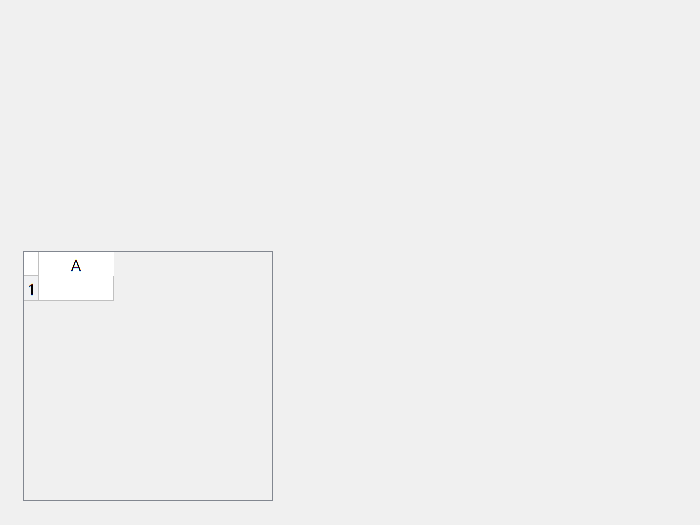


T2 =

	javahandle_withcallbacks.com.mathworks.hg.peer.UitablePeer



T2 = uitable(T)

## Exercise 3

The output of the code indicates that the knapsack problem was solved successfully. The optimal objective value is -4331.111111, which means that the maximum value of items that can be put into the knapsack with a capacity of 100 is -4331.111111. The code also found that the relative gap between the optimal objective value and the upper bound is 13.15%, which is less than the default tolerance of 15%. This means that the code is confident that the optimal objective value is close to the true optimal objective value.

The code also applied one strong CG cut, which is a type of constraint generation that can help to improve the performance of the intlinprog function. The code also found that the intcon variables are integer within tolerance, which means that the solutions to the integer constraints are within the specified tolerance of the default value of 1e-05.

Overall, the output of the code indicates that the knapsack problem was solved successfully and that the optimal solution was found.


close all; clc; clear

w=[2 15 15 42 15 10 20 25 5 16 15 23]; % weights
v=[200 500 600 1000 300 600 800 800 300 600 600 1000]; % values
W=100; % capacity
A=[ w                                    % constraint 1
    0  1  0  0  0  0  0  0  1  0  0  0;  % constraint 3
    0 -1  2  0  0 -1  0  0  0  0  0  0;  % constraint 4
    0  0  0  0  0  0  0 -1  1  0  0  0;  % constraint 7
    0  0  0  0  0  0  0  0  0  0 -1 -1]; % constraint 8
   
%   1  3  4  7  8  
b= [W  1  0  0 -1];

Aeq=[ 1  0  0  0  0  0  0  0  0  0  0  0;  % constraint 2
      0  0  0  1 -1  0  0  0  0  0  0  0;  % constraint 5
      0  0  0  0  0  1  1  1  0  0  0  0]; % constraint 6

%     2  5  6
beq=[ 1  0  2];
lb=zeros(1,12);ub=ones(1,12);
[sol, val]=intlinprog(-v,1:12,A,b,Aeq,beq,lb,ub);

LP:                Optimal objective value is -4331.111111.                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -3800.000000.                                                     
                   Relative gap is 13.15%.                                                         

Cut Generation:    Applied 1 strong CG cut.                                                         
                   Lower bound is -4300.000000.                                                     
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are <a


solution = sol

solution =     1.0000
    1.0000
    1.0000
         0
         0
    1.0000
    1.0000
         0
         0
         0


backpack_weight = sum(sol.*w')

backpack_weight = 100.0000

backpack_value = val

backpack_value = -4.3000e+03

## Exercise 4


close all; clear; clc

n=9;  % # nodes
m=20; % # edges

%   [ 1  2  3  4  5  6  7  8  9 10 11 12 13 14 15 16 17 18 19 20];
S=  [ 1  3  3  3  5  5  5  6  6  6  7  7  7  7  7  8  8  9  9  9]; % starting node
E=  [ 5  7  8  9  4  6  7  2  5  7  2  4  5  6  9  7  9  2  6  8]; % ending node
C=  [ 3  6  4  5  9  5  4  6  6  4  5  4  7  3  5  5  3  5  2  5]; % cost
W=  [ 9  4  3  2  4  2  5  4  5  4  5  4  5  2  4  5  4  3  5  3]; % capacity

Aeq=[ 1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0; %constraint for node 1
      0  0  0  0  0  0  0 -1  0  0 -1  0  0  0  0  0  0 -1  0  0; %constraint for node 2
      0  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0; %constraint for node 3
      0  0  0  0 -1  0  0  0  0  0  0 -1  0  0  0  0  0  0  0  0; %constraint for node 4
     -1  0  0  0  1  1  1  0 -1  0  0  0 -1  0  0  0  0  0  0  0; %constraint for node 5
      0  0  0  0  0 -1  0  1  1  1  0  0  0 -1  0  0  0  0 -1  0; %constraint for node 6
      0 -1  0  0  0  0 -1  0  0 -1  1  1  1  1  1 -1  0  0  0  0; %constraint for node 7
      0  0 -1  0  0  0  0  0  0  0  0  0  0  0  0  1  1  0  0 -1; %constraint for node 8
      0  0  0 -1  0  0  0  0  0  0  0  0  0  0 -1  0 -1  1  1  1];%constraint for node 9

 
    % 1  2  3  4  5  6  7  8  9 node
beq=[ 9 -7  6 -8  0  0  0  0  0]'; % supplies and demands
lb=zeros(20,1);
ub=W;
[xmin, fval, flag]=linprog(C,[],[],Aeq,beq,lb,ub);

Optimal solution found.




if flag==1
    fprintf('Function converged to a solution x.')
end

Function converged to a solution x.


from_to = [S;E];
solution = [S;E;xmin']

solution =      1     3     3     3     5     5     5     6     6     6     7     7     7     7     7     8     8     9     9     9
     5     7     8     9     4     6     7     2     5     7     2     4     5     6     9     7     9     2     6     8
     9     4     0     2     4     0     5     0     0     0     5     4     0     0     0     0     0     2     0     0


Cost_flow = fval

Cost_flow = 168


nodes = 1:n;
supply = nodes.*(beq>0)';
supply = supply(supply~=0)

supply =      1     3



from_to = from_to.*(xmin~=0)';
from_to = from_to(from_to~=0);
from_to = reshape(from_to,2,length(from_to)/2)

from_to =      1     3     3     5     5     7     7     9
     5     7     9     4     7     2     4     2


S = from_to(1,:);
E = from_to(2,:);
flow = xmin(xmin~=0);

x = [0 6 3 3 2 4 3 2 4]

x =      0     6     3     3     2     4     3     2     4


y = [3 3 0 6 4 4 3 2 2]

y =      3     3     0     6     4     4     3     2     2


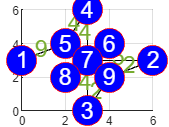


hold on
for i=1:length(S)
    p1 = [x(S(i)) y(S(i))];            % First Point
    p2 = [x(E(i)) y(E(i))];      % Second Point
    dp = p2-p1;                      % Difference
    quiver(p1(1),p1(2),dp(1),dp(2), ...
        'AutoScale','on', ...
        'AutoScaleFactor',1, ...
        'MaxHeadSize',0.5, ...
        'Color','black')
    text(x(S(i))-0.1+dp(1)/2,y(S(i))+0.2+dp(2)/2,num2str(flow(i)),'Color','#77AC30','FontSize',15,'HorizontalAlignment','center')
end
for i=1:n
plot(x(i),y(i),'o','MarkerSize',20,'Color','r','MarkerFaceColor','b')
text(x(i),y(i),num2str(i),'Color','w','FontSize',15,'HorizontalAlignment','center')
end
grid on

## Exercise 5


close all; clear; clc

n=10; % number of points
m = n*(n-1);
% P=zeros(n,2); % inicialize point's coordinates
D=zeros(n,n); % inicialize distance matrix
P=rand(n,2)*10; % generate n random points
rectangle('Position',[0 0 10 10])
axis([-1 11 -1 11])
hold on
plot(P(:,1),P(:,2),'rx') % draw the points as red crosses
for i=1:(n-1) % calculate distance matrix
    for j=(i+1):n
        D(i,j)=norm(P(i,:)-P(j,:));
        D(j,i)=D(i,j);
    end
end

%% Calculates the vector f
%
% f= # of cities, D(i,j)=distance from city i to city j
% f must be a vector of 2·n·(n-1) coeficients associated to the variables
% x(1), x(2),...,x(n·(n-1)), y(1), y(2),...,y(n·(n-1))
% writes the distance matrix D in a one dimensional vector
f=reshape(D,1,n*n);
% deletes variables related with edges ii (size(f)=n*(n-1))
f=f(f~=0);
% add to the previous vector n·(n-1) coeficients associated to the y variables
f=[f,zeros(1,n*(n-1))];

%% A matrix

o = ones(1,n-1);
z = zeros(1,n-1);
e = eye(n);

A1 = [];
for i=1:n
    r = [];
    for j=1:n
        if i==j
            r = [r,o];
        else
            r = [r,z];
        end
    end
    A1(i,:) = r;
end

A2 = [];
for i=1:n
    A2 = [A2,z];
    for j=1:n
        if i==n
            break
        end
        A2 = [A2,e(i,1:n-1)];
    end
end
A2 = reshape(A2',[],n)';

A1;
A2;
A3=A1-A2;
A4=-(n-1)*eye(m);

O = zeros(n,m);

Aeq = [A1  O;
       A2  O;
        O A3];
beq = [ones(2*n,1);n-1;-ones(n-1,1)];

A = [A4, eye(m)];
b = zeros(m,1);
lb=zeros(2*m,1);
ub=[ones(m,1);100*ones(m,1)];
[x,fval]=intlinprog(f,1:(2*m),A,b,Aeq,beq,lb,ub);

LP:                Optimal objective value is 31.688372.                                            

Cut Generation:    Applied 9 implication cuts,                                                      
                   3 flow cover cuts, 2 strong CG cuts,                                             
                   1 Gomory cut, and 2 zero-half cuts.                                              
                   Lower bound is 32.059210.                                                        

Heuristics:        Found 3 solutions using diving.                                                  
                   Upper bound is 34.394695.                                                        
                   Relative gap is 6.60%.                                                          

Cut Generation:    Applied 2 Gomory cuts,                                                           
                   9 implication cuts, 2 flow cover cuts,                                

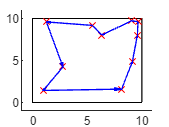


dist = x.*f';
m1 = reshape(dist(1:m),[],n-1);         % Matrix with n-1 columns
m2 = [zeros(1,n-1); m1];                % Adding diagonal zeros
M = reshape([reshape(m2,[],1);0],[],n);  % Reshaping final matrix

%% Plotting traveling lines

l = [];
for i=1:n
    l(i) = find(M(i,:));
end
for i=1:n
%     line([P(i,1),P(l(i),1)],[P(i,2),P(l(i),2)])
    p1 = [P(i,1) P(i,2)];            % First Point
    p2 = [P(l(i),1) P(l(i),2)];      % Second Point
    dp = p2-p1;                      % Difference
    quiver(p1(1),p1(2),dp(1),dp(2), ...
        'AutoScale','on', ...
        'AutoScaleFactor',1, ...
        'MaxHeadSize',0.3, ...
        'Color','b')
end

## Conclusion

Everything that I was doing is explained in the code and by comments. I tried to display the solution the best way I could so there was no cocnclusion or explanation needed for each of the exercises. I think I found all the optimal solutions.